`直接调用函数```normrnd```生成服从正态分布的随机数：`

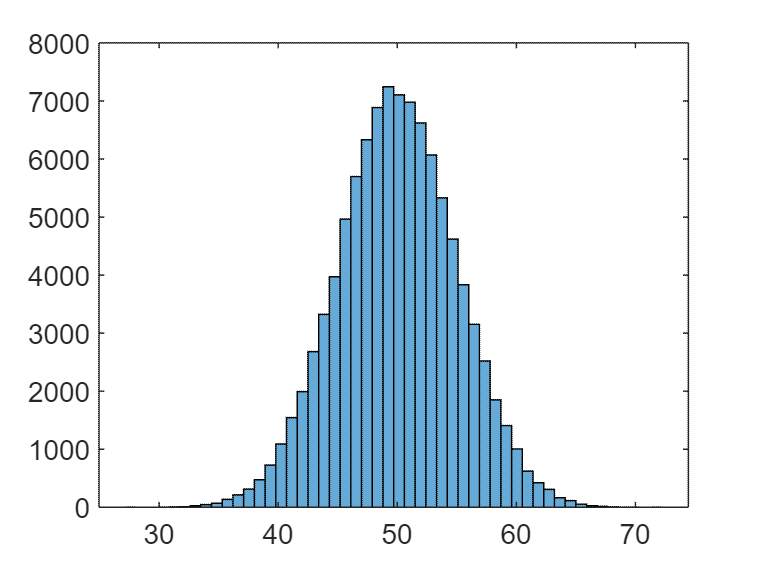

clear;
mu = 50;
sigma =5;
x = normrnd(mu,sigma,100000,1);
figure
histogram(x,50);% 直方图50族

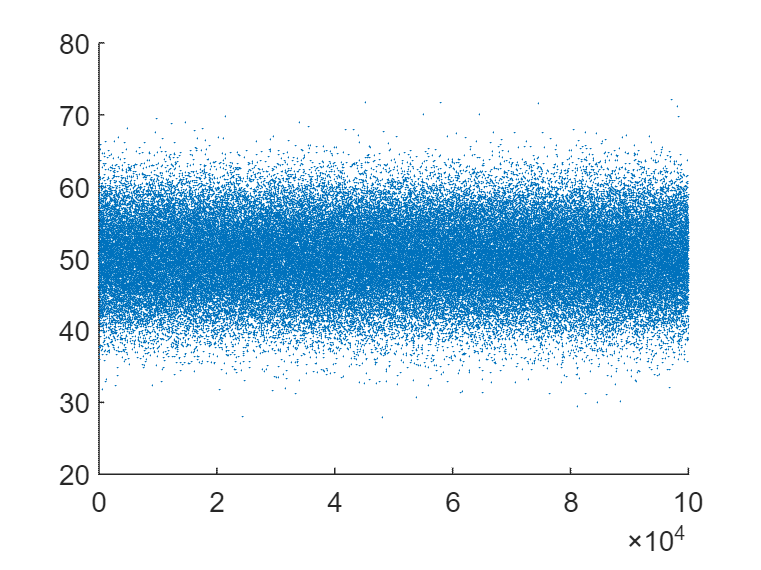

i = 1:1:size(x);
scatter(i,x,.3,"filled")% 散点图

`函数`randn`是函数`normrnd`的简化版，生成服从均值为0，方差为1的正态分布的随机数：`

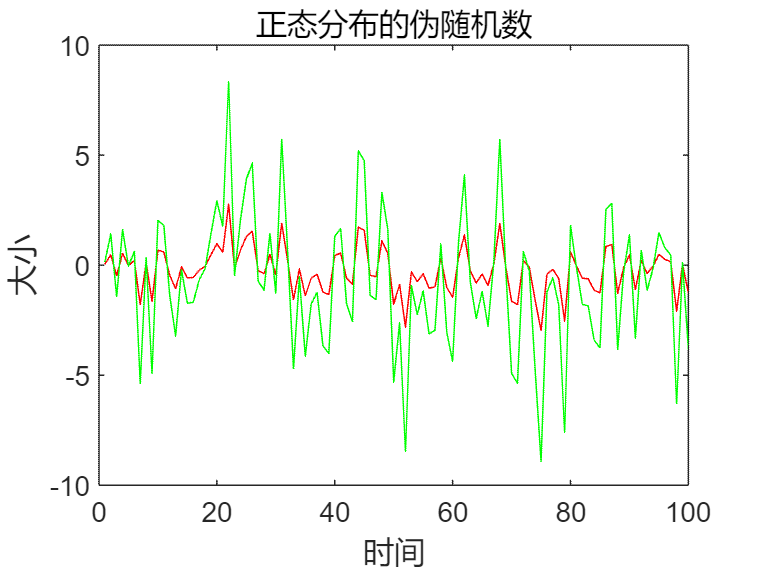

T = (1 : 100).'; % 离散的时间序列，单位是s
X = randn(100, 1);
Y = 3 * X;
figure(1);
plot(T, X(:, 1), 'r');
hold on
plot(T, Y(:, 1), 'g');
title('正态分布的伪随机数');
xlabel('时间'); ylabel('大小');